%Generate testing data, similar to above code but only one sequence of
%integers are generated 
rng(0); 
M=16;
window = 4;
nb = 10014;

%communication things 
constDiagram = comm.ConstellationDiagram('SamplesPerSymbol',1, ...
    'SymbolsToDisplaySource','Property','SymbolsToDisplay',100);
awgnChan = comm.AWGNChannel('BitsPerSymbol', 4); %create awgn channel object
LO = dsp.SineWave("Frequency", 1.5e9, "ComplexOutput", true, "SampleRate", (1e-6)/8, "SamplesPerFrame", 8*nb); 
y = LO(); %up conversion

txfilter = comm.RaisedCosineTransmitFilter(); %tx srrc
rxfilter = comm.RaisedCosineReceiveFilter(); %rx srrc

for EbNo = -2:23
    awgnChan.EbNo = EbNo; 
    mkdir(sprintf('SNR_%d', EbNo));
    cd(sprintf('SNR_%d', EbNo)); 
    for i = 1:10
        msg = randi([0 sum(M)-1], nb, 1);
        symbols = dvbsapskmod(msg, M, 's2x'); 
        txfilterData = txfilter(symbols); 
        txData = txfilterData.*y; %upconvert
        txData = awgnChan(txData);
        
        rxData = txData.*conj(y); %down convert
        rx = rxfilter(rxData); %SRRC filter
        
        d = finddelay(symbols, rx); %need to remove delay before windowing
        rx = rx((d+1):end); %get rid of filter delay 
        symbols = symbols(1:(end-d));
        
        train_data = makeInputMat(rx,window);
        train_data = train_data(:,1:end-window);
        symbols = symbols(1+window:end);
        target = round([real(symbols) imag(symbols)],5)';
        
        train_data = train_data'; 
        
        filename_test = sprintf('DVBSAPSK_pred_%d', i); 
        save(filename_test, 'train_data', 'target'); 
    end 
    cd ..
end 

%Evaluate and plot performance 
%DVBS-16APSK
NN_out = zeros(1,26); 
j= 1; 
for EbNo = -2:23
    disp(j)
    cd(sprintf('SNR_%d', EbNo)); 
    ber = zeros(1,10);
    for i = 1:10
        f_og = sprintf('DVBSAPSK_pred_%d.mat', i); %test sequence, generated above
        f_test = sprintf('DVBSAPSK_out_%d.mat', i); %from NN
        
        load(f_og); 
        load(f_test);
        
        pred = complex(pred(:,1), pred(:, 2));
        target = target';
        target_cp= complex(target(:,1), target(:, 2));
        
        %BER
        demodData_NN = dvbsapskdemod(pred, M, 's2x'); 
        demodData_ideal = dvbsapskdemod(target_cp, M, 's2x');
        
        demodData_NN = cast(demodData_NN,'like',demodData_ideal); %matching type
        
        %calculate BER
        data_bit = int2bit(demodData_ideal, 4); %convert to bit
        output_bit = int2bit(demodData_NN, 4);%convert to bit
        
        d = finddelay(data_bit,output_bit); 
        errorRate = comm.ErrorRate('ReceiveDelay', abs(d));
        err = errorRate(data_bit, output_bit); %get bit error
        ber(i)= err(1)*100;
    end 
   cd .. 
   NN_out(j) = mean(ber); 
   j = j+1;
end 

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10

    11

    12

    13

    14

    15

    16

    17

    18

    19

    20

    21

    22

    23

    24

    25

    26



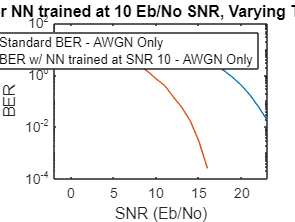


%plot outcome
path_awgn = 'C:\Users\Martha Ca$h\Desktop\School\Grad School\Research\DVBS2X Simulation\AWGN Model\BER Plot\ber.xls';
awgn_ber = readmatrix(path_awgn); 
awgn_ber = awgn_ber.*100; 

snr = -2:23; 
semilogy(snr, awgn_ber, snr, NN_out)
title('BER vs. SNR for NN trained at 10 Eb/No SNR, Varying Test Sequence SNR')
xlabel('SNR (Eb/No)')
ylabel('BER')
legend('Standard BER - AWGN Only', 'BER w/ NN trained at SNR 10 - AWGN Only');